# **Vectores y Matrices**

**Vectores**

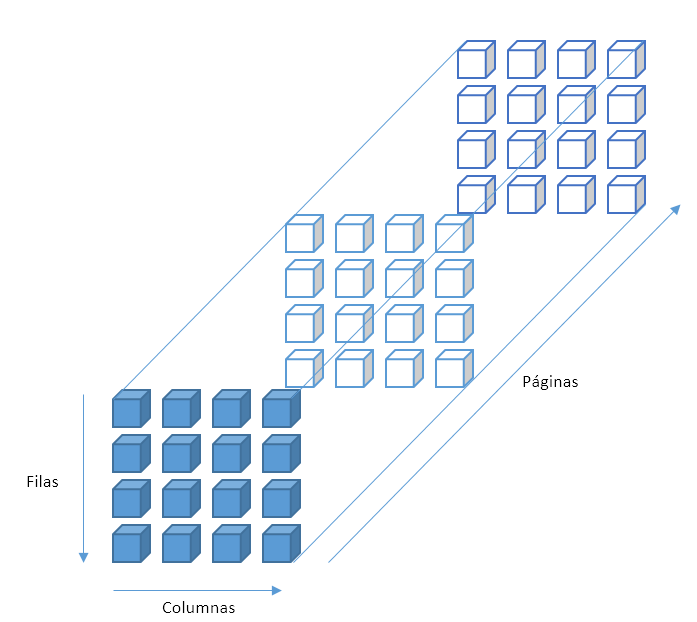

## Introducción

MATLAB está diseñado para trabajar eficientemente con vectores (*arrays*), matrices y otros arreglos de datos. 

Las matrices y arrays son arreglos de datos del mismo tipo. Tanto las matrices como los arrays se crean en general utilizando los corchetes [ ], aunque, como veremos más adelante, también existen funciones que crean vectores y matrices de especial utilidad. 

La diferencia entre ambos es que los arrays son arreglos de una única dimensión mientras que las matrices son de dos o más dimensiones. 

## Básico

help plot

plot - 2-D line plot

    This MATLAB function creates a 2-D line plot of the data in Y versus the
    corresponding values in X.

    plot(X,Y)
    plot(X,Y,LineSpec)
    plot(X1,Y1,...,Xn,Yn)
    plot(X1,Y1,LineSpec1,...,Xn,Yn,LineSpecn)
    plot(Y)
    plot(Y,LineSpec)
    plot(___,Name,Value)
    plot(ax,___)
    h = plot(___)

    See also <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/gca.html">gca</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/hold.html">hold</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/legend.html">legend</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/loglog.html">loglog</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/plot3.html">plot3</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/title.html">title</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/xlabel.html">xlabel</a>, <a href="https://www.ma

a=8

a = 8

3+5

ans = 8

ans*2;
Num=10

Num = 10

numero2=45

numero2 = 45

str='Hola Mundo'

str = 'Hola Mundo'

b=Num+numero2    

b = 55

curva = 2*pi

curva = 6.2832

pi = 5;
curva = 2*pi

curva = 10

vect=[1 2 3 4 5 6 7]

vect =      1     2     3     4     5     6     7


vectcol=[2;4;5;7;-1;0]

vectcol =      2
     4
     5
     7
    -1
     0


## Vector fila

Los vectores fila son arreglos de datos en los que la longitud de la primera dimensión es 1.

Para crear un vector fila podemos introducir los valores entre corchetes y separados por comas.  

a=[1, 2, 5, 9]

a =      1     2     5     9


a0 = zeros(1,10)

a0 =      0     0     0     0     0     0     0     0     0     0


a1 = ones(1,10)

a1 =      1     1     1     1     1     1     1     1     1     1


Es posible omitir las comas.

a2=[5 9 0 12]

a2 =      5     9     0    12


a3=[5745 12325 -6.8678]

a3 = 	1.0e+04 *

    0.5745    1.2325   -0.0007



%vectores de caracteres
a4=[1 'dos' 3 'cuatro' 5]

a4 = 'doscuatro'

a4(1)+a4(3)

ans = 112

str2double(a4(1))+str2double(a4(3))

ans = NaN

Podemos saber la longitud de cualquier vector o matriz utilizando los comandos *length* o *size*.

El comando *length* devuelve la longitud de la primera dimensión mayor a 1 de un vector o matriz. El comando *size* devuelve el tamaño de todas las dimensiones si no se especifica la dimensión.

longitud=length(a2)

longitud = 4


[filas,columnas]=size(a2)

filas = 1

columnas = 4


filas=size(a2,1)

filas = 1

columnas=size(a2,2)

columnas = 4

También podemos ver en cualquier momento las dimensiones de los arreglos en la pestaña del *workspace* si se marca esta opción de visualización y mediante el comando *whos.*

whos

  Name          Size            Bytes  Class     Attributes

  Num           1x1                 8  double              
  a             1x4                32  double              
  a0            1x10               80  double              
  a1            1x10               80  double              
  a2            1x4                32  double              
  a3            1x3                24  double              
  a4            1x12               24  char                
  ans           1x1                 8  double              
  b             1x1                 8  double              
  columnas      1x1                 8  double              
  curva         1x1                 8  double              
  filas         1x1                 8  double              
  longitud      1x1                 8  double              
  numero2       1x1                 8  double              
  pi            1x1                 8  double              
  str           1x10               20  

Para acceder a los elementos de los arrays utilizaremos los paréntesis de la siguiente forma. Los índices en MATLAB empiezan en 1. 

a3(3)       % Accedemos al tercer elemento del array a3

ans = -6.8678

a3(2)

ans = 12325

a3(2)+a3(3) % Podemos hacer operaciones directamente accediendo a los elementos de los arrays

ans = 1.2318e+04

Se puede definir un array o matriz indicando directamente la posición de los elementos.

a4(2)=35

a4 = '#oscuatro'

Observad que en este caso hemos indicado que el segundo elemento del array a4 debe valer 35. Como no hemos especificado el primer elemento del arreglo MATLAB automáticamente le asignará un valor 0. Completemos la definición del array.

a4(3)=26, a4(4)=32, a4(1)=5

a4 = '#scuatro'

a4 = '# cuatro'

a4 = '# cuatro'

Observad que cuando definimos un vector en MATLAB, éste aumenta su tamaño cuando es necesario. Sin embargo, cuando se intenta acceder a un elemento que excede las dimensiones del array, MATLAB nos mostrará un mensaje de error.

#### Ejercicio 1

Cree un vector fila de longitud 8 con los primeros números primos: 

numeros_primos = [2, 3, 5, 7, 11, 13, 17, 19]

numeros_primos =      2     3     5     7    11    13    17    19


El operador : permite crear series numéricas.

Podemos crear una serie numérica de la siguiente forma:

 ini=0

ini = 0

 paso=5 

paso = 5

 fin=100

fin = 100

 serie=ini:paso:fin

serie =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


 serie2=1:20

serie2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


Si no se especifica el paso, éste tiene como valor por defecto 1.

#### Ejercicio 2

Cree un vector columna cuyos elementos estén comprendidos entre 15 y 150 con un paso 5. Utilice los dos puntos " : " para crear los elementos del vector. Compruebe el tamaño del vector.

vector_columna = transpose([15:5:150])

vector_columna =     15
    20
    25
    30
    35
    40
    45
    50
    55
    60


longitud       = size(vector_columna)

longitud =     28     1


tamano_vector  = longitud(1)

tamano_vector = 28

## Vector columna

En los vectores columna la dimensión 2 tiene un valor de 1. Los elementos se separan por " ; "

b=[12;56;21;17]

b =     12
    56
    21
    17


size(b)

ans =      4     1


El apóstrofe, ' , transpone un vector o matriz y puede resultar útil en ocasiones para crear vectores columna a partir de vectores fila.

b2=[15 67 23 68]'

b2 =     15
    67
    23
    68


b3=a2'

b3 =      5
     9
     0
    12


Es posible concatenar vectores para crear arrays de mayores dimensiones.

X=1:5       % Vectores fila

X =      1     2     3     4     5


Y=10:-1:6

Y =     10     9     8     7     6


conc=[X Y]  % Concatenación horizontal

conc =      1     2     3     4     5    10     9     8     7     6


X2=X'

X2 =      1
     2
     3
     4
     5


Y2=Y'

Y2 =     10
     9
     8
     7
     6


conc2=[X2;Y2]

conc2 =      1
     2
     3
     4
     5
    10
     9
     8
     7
     6


## Matrices

Las matrices se crean de igual forma que los *arrays *pero definiendo los elementos de las filas y columnas. Una matriz debe tener el mismo número de elementos en todas las filas y columnas.

A=[20 99 43;  45 27 77; 81 9 -3]    % Se crea una matriz de 3 filas y 3 columnas

A =     20    99    43
    45    27    77
    81     9    -3


size(A)

ans =      3     3


Se pueden definir cada una de las posiciones exactamente como en el caso de los arrays indicando la posición de cada una de las dimensiones.

A(2,1)=25       % Asignamos al elemento de la segunda fila y primera columna el valor 25

A =     20    99    43
    25    27    77
    81     9    -3


A(2,2)=5+7      

A =     20    99    43
    25    12    77
    81     9    -3




A(2)=0          % Es conveniente definir las posiciones de todas las dimensiones De lo contrario MATLAB 

A =     20    99    43
     0    12    77
    81     9    -3


                % interpretará que es el orden del elemento cogiendo en
                % primer lugar las columnas

A(5)

ans = 12

Para acceder a un subconjunto de los valores de una matriz se utilizan los dos puntos :

A(1,:)          % Devuelve todos los elementos de la primera fila

ans =     20    99    43


A(:,2)          % Devuelve todos los elementos de la segunda columna

ans =     99
    12
     9


A(1:2,1)        % Devuleve los dos primeros elementos de la primera columna

ans =     20
     0


La palabra clave *end* permite indicar el último elemento de una dimensión.

Las matrices pueden tener más de dos dimensiones. Esto es de especial utilidad cuando se trabaja con imágenes o videos.

A2(1,1,1)=1, A2(2,2,1)=1, A2(3,3,1)=1, A2(2,1,2)=5       % Creamos una matriz de 3 x 3 x 2

A2 = 1

A2 =      1     0
     0     1


A2 =      1     0     0
     0     1     0
     0     0     1


A2 = A2(:,:,1) =

     1     0     0
     0     1     0
     0     0     1


A2(:,:,2) =

     0     0     0
     5     0     0
     0     0     0


size(A2)

ans =      3     3     2


A2(:,:,3)=[1 1 1; 1 1 1; 1 1 1]

A2 = A2(:,:,1) =

     1     0     0
     0     1     0
     0     0     1


A2(:,:,2) =

     0     0     0
     5     0     0
     0     0     0


A2(:,:,3) =

     1     1     1
     1     1     1
     1     1     1


size(A2)

ans =      3     3     3


## Otras formas de crear vectores y matrices

Existen funciones que nos facilitan la labor de crear matrices y arrays. 

Un ejemplo de este tipo de funciones son *linspace*, *ones, zeros, eye o rand*, entre otras.

La función *linspace* es una función de gran utilidad que permite crear un vector de una longitud determinada cuyos elementos están equiespaciados entre el valor inferior y el superior.

b4=linspace(0,1,1001)   % Crea un array entre 0 y 1, incluidos, con 10001 puntos

b4 =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


Busque la ayuda sobre las funciones *ones, zeros, eye *y* diag* y observe el resultado obtenido con las siguientres instrucciones.

B=ones(4,3)       % Creamos una matriz de 4 x 3 cuyos elementos son 1.

B =      1     1     1
     1     1     1
     1     1     1
     1     1     1


B2=2*ones(1,5)

B2 =      2     2     2     2     2


B3=2+ones(7)      % Si solo se especifica un valor MATLAB lo interpreta como una matriz cuadrada

B3 =      3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3



B4=zeros(5),B4(5,3)=6

B4 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


B4 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     6     0     0



B5=eye(3)         % Matriz identidad

B5 =      1     0     0
     0     1     0
     0     0     1


B6=rand(6)

B6 =     0.8147    0.2785    0.9572    0.7922    0.6787    0.7060
    0.9058    0.5469    0.4854    0.9595    0.7577    0.0318
    0.1270    0.9575    0.8003    0.6557    0.7431    0.2769
    0.9134    0.9649    0.1419    0.0357    0.3922    0.0462
    0.6324    0.1576    0.4218    0.8491    0.6555    0.0971
    0.0975    0.9706    0.9157    0.9340    0.1712    0.8235


#### Ejercicio 3

Dividir el intervalo [0,$\pi$] en 100 intervalos iguales.

division_intervalo = linspace(0,pi)

division_intervalo =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


#### Ejercicio 4

Cree una matriz de 4x4 elementos cuyos elementos de la diagonal principal sean igual a 2. Los restantes elementos serán valores distintos entre sí, escogidos a voluntad. Utilice como mínimo alguna de las siguientes funciones: *diag, eye, ones, zeros, tril *o* triu.*

% Funcion del toolbox "Statistics and Machine Learning"
matriz = reshape(randsample([3:20],4^2),[4 4]);
matriz(eye(size(matriz))==1) = 2

matriz =      2     4    12     3
    20     2    14    15
    11     7     2    16
    17    13    18     2


## Operaciones con vectores y matrices

En las operaciones con vectores y matrices se debe tener en cuenta si se éstas operaciones se producen con un escalar o con otra matriz o vector.

### Suma y resta

Cuando se realiza la suma (o resta) entre un escalar y una matriz (o vector), el escalar se suma a todos los elementos. 

A=[1 3 5; 5 6 -1; 0 3 2]

A =      1     3     5
     5     6    -1
     0     3     2


A+2

ans =      3     5     7
     7     8     1
     2     5     4


Si la operación se produce entre dos matrices, éstas deben ser del mismo tamaño y se realiza elemento a elemento.

B=[6 -1 0; 9 0.3 -1; 1/8 1 1]

B =     6.0000   -1.0000         0
    9.0000    0.3000   -1.0000
    0.1250    1.0000    1.0000


A2=A+B

A2 =     7.0000    2.0000    5.0000
   14.0000    6.3000   -2.0000
    0.1250    4.0000    3.0000


### Multiplicación

La multiplicación por un escalar se produce elemento a elemento.

En caso de una multiplicación entre dos matrices tenemos dos opciones. 

- La multiplicación de matrices. Tened en cuenta que el número de columnas de la primera matriz debe ser igual al número de filas de la segunda matriz.

M=A*B

M =    33.6250    4.9000    2.0000
   83.8750   -4.2000   -7.0000
   27.2500    2.9000   -1.0000


        2. Multiplicar elemento a elemento, utilizando el operador " .* "

M2=A.*B

M2 =     6.0000   -3.0000         0
   45.0000    1.8000    1.0000
         0    3.0000    2.0000


### División

Al igual que en el caso de la multiplicación la operación con un escalar se realiza sobre todos los elementos de la matriz o vector.

En el caso de dos matrices es posible realizar la operación elemento a elemento utilizando el operador " ./ ".

Utiliar el operador " / " equivale a $A/B=A*B^{-1}$, es decir, multiplicar por la derecha con la matriz inversa. 

Si utilizamos el operador " \ " equivale a $A\backslash B=A^{-1} *B$. Vamos a comprobar que es así:

Div=A/B

Div = 3×3
    1.1071   -0.6869    4.3131
   -3.3804    2.7843    1.7843
   -0.5583    0.3397    2.3397


B1=inv(B)

B1 = 3×3
    0.0768    0.0591    0.0591
   -0.5391    0.3545    0.3545
    0.5295   -0.3619    0.6381


A*B1

ans = 3×3
    1.1071   -0.6869    4.3131
   -3.3804    2.7843    1.7843
   -0.5583    0.3397    2.3397



Divl=A\B

Divl = 3×3
    2.7813   -0.7550   -0.7000
   -0.6458    0.6100    0.4000
    1.0313   -0.4150   -0.1000


A1=inv(A)

A1 = 3×3
    0.2500    0.1500   -0.5500
   -0.1667    0.0333    0.4333
    0.2500   -0.0500   -0.1500


A1*B

ans = 3×3
    2.7813   -0.7550   -0.7000
   -0.6458    0.6100    0.4000
    1.0313   -0.4150   -0.1000


### Transposición

Mediante la transposición intercambiamos las filas y las columnas. Esto se realiza mediante el uso del apóstrofe " ' ".

En caso de matrices de números complejos este operador realiza la transposición conjugada. Para no realizar la conjugada utilizaremos el operador " .' "

A2=[3+2i 8 0; 1 2-1i 0; -7 3 4i]

A2 = 3×3
   3.0000 + 2.0000i   8.0000 + 0.0000i   0.0000 + 0.0000i
   1.0000 + 0.0000i   2.0000 - 1.0000i   0.0000 + 0.0000i
  -7.0000 + 0.0000i   3.0000 + 0.0000i   0.0000 + 4.0000i


A2'

ans = 3×3
   3.0000 - 2.0000i   1.0000 + 0.0000i  -7.0000 + 0.0000i
   8.0000 + 0.0000i   2.0000 + 1.0000i   3.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 4.0000i


### Potenciación

El operador " ^ " para exponentes enteros mayores a 1 equivale a multiplicar la matriz o vector tantas veces como indica el exponente. Recuerde que por lo general la potencia de una matriz será posible calcularla cuando se trate de matrices cuadradas.

Usando el punto delante del operador realizaremos la operación elemento a elemento, " .^ ".

A3=A^2

A3 = 3×3
    16    36    12
    35    48    17
    15    24     1


### Autovalores y autovectores

Al multiplicar un vector por una matriz, el resultado por lo general es un vector con una magnitud y dirección distintas a las del vector original. Se puede interpretar una matriz como una función que convierte un vector en otro vector y de este modo transforma el espacio original. Puede darse que algunos vectores del espacio original mantengan la dirección en el nuevo espacio. A estos vectores se les llama autovectores. Se llama autovalor al factor que modifica la norma (longitud) de estos vectores durante la transformación. El cálculo de autovalores y autovectores es común en muchos campos de la ingeniería y nos puede proporciona información muy importante sobre estas transformaciones. 

Formalmente se debe cumplir que $A\upsilon =\lambda \upsilon$, con $\upsilon \not= 0$, siendo $A$ una matriz, $\upsilon$ un autovector y $\lambda$ un autovalor.

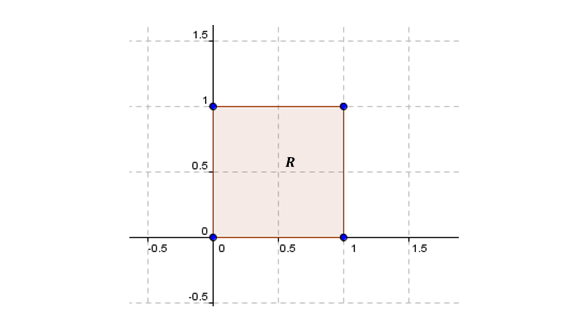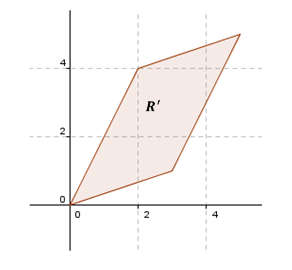

Para el cálculo de los autovalores utilizaremos la función *eig*.

A4=[3 2; 1 4]

A4 = 2×2
     3     2
     1     4


[V,D]=eig(A4)

V = 2×2
   -0.8944   -0.7071
    0.4472   -0.7071


D = 2×2
     2     0
     0     5


#### Ejercicio 5

Resolver en forma matricial ([A^-1][A]·[X]=[A^-1][B]) el siguiente sistema de ecuaciones:

Calcule el rango de la matriz, el determinante y los autovalores y autovectores. Utilice las funciones *rank *y* det.*


A = [1, 3, -5;-1, 1 3;2, 2, 1];
B = [4;6;-10];

X = inv(inv(A)*A)*(inv(A)*B)

X = 3×1
   -6.6111
    2.0556
   -0.8889



rango_A        = rank(A)

rango_A = 3

determinante_A = det(A)

determinante_A = 36


[Autovectores, Autovalores] = eig(A)

Autovectores = 3×3
  -0.8416 + 0.0000i  -0.8416 + 0.0000i  -0.1667 + 0.0000i
   0.2419 - 0.2953i   0.2419 + 0.2953i   0.8100 + 0.0000i
  -0.0474 + 0.3792i  -0.0474 - 0.3792i   0.5623 + 0.0000i


Autovalores = 3×3
  -0.1441 + 3.3056i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.1441 - 3.3056i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.2883 + 0.0000i


Autovectores

Autovectores = 3×3
  -0.8416 + 0.0000i  -0.8416 + 0.0000i  -0.1667 + 0.0000i
   0.2419 - 0.2953i   0.2419 + 0.2953i   0.8100 + 0.0000i
  -0.0474 + 0.3792i  -0.0474 - 0.3792i   0.5623 + 0.0000i


Autovalores

Autovalores = 3×3
  -0.1441 + 3.3056i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.1441 - 3.3056i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.2883 + 0.0000i


## Ejercicios adicionales

**Introducción a MATLAB**

[https://matlabacademy.mathworks.com/R2020a/es/portal.html?course=gettingstarted](https://matlabacademy.mathworks.com/R2020a/es/portal.html?course=gettingstarted)